# optimal exptl design

this is a forward problem only reproduce Beck and Arnold, p. 442, Fig. 8.10 exponential decay eta = beta(1)*exp(-beta(2)*t) Eq. 8.4.3

## set up times

close all
clear
t=0:0.1:2;%time
t=t';%make t a column
m=length(t);

## parameter values

beta(1)=1;% Because it's normalized
beta(2)=1;% Because it's normalized

## Call and plot the function

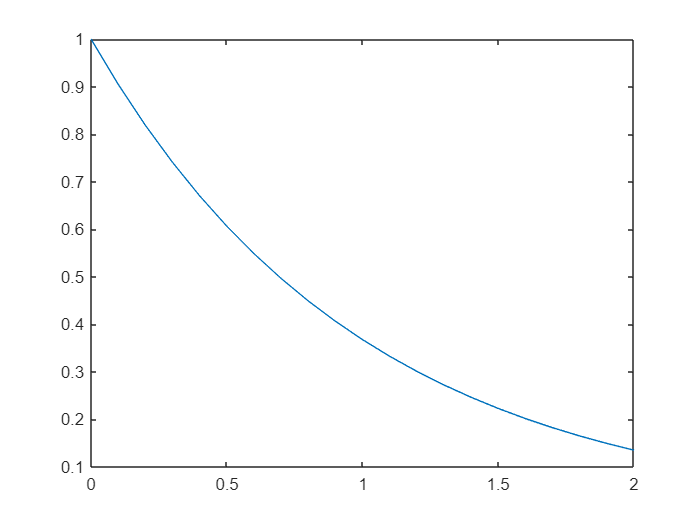

Y=expdecay(beta,t);
plot(t,Y)

%Make sure Y and t have exactly the same dimensions
%Do not allow Y to be a row and t to be a column.  Make both of them
%columns

## Compute C11, C12,...delta for opt exptl design

fname=@expdecay;
%Xp are the scaled sensitivity coefficients
Xp=SSC_V4(beta,t,fname);%compute scaled sensitivity coefficients as a cell array
p=length(beta);

## compute entire C matrix

for i=1:p 
    for j=1:p
        intgrnd=Xp{i}.*Xp{j}; %integrand for Eq. 8.3.5, Beck and Arnold, p. 434
        C{i,j}=(1./t).*cumtrapz(t,intgrnd);  % trapezoidal rule integral of Eq. 8.3.5, Beck and Arnold, p. 434
        clear intgrnd
    end
end

## to compute delta, must set up the C matrix for each time

%extract C into a 3-D matrix we call "CC"
for i=1:p
    for j=1:p
        CC(i,j,:)=C{i,j}; %gives a 3D matrix that is m (depth) in time
    end
end

## For your project, you must set all CC(:,:,1) (first page) values to the appropriate

number, based on your project

CC(:,:,1)=0;%beginning values at time = 0 are zero
CC(1,1,1)=1;%except for C11, for the initial value
delta(1)=0; %determinant at time zero = 0.
for k=2:m
    delta(k)=det(CC(:,:,k));
end
% delta=sqrt(delta);%converts units of delta to same as units for C

## convert 3D to 2D for plotting

%C matrix is symmetrical, so need only one half
i=1;
d=1;
% "Cp" is "C for plotting"
% Cp(1) holds C11; Cp(2) holds C12;
%for first row, i =1
for j=1:p
    Cp(d,:)=CC(i,j,:); %copies the Cij values for all times and stores in Cp(d,:)
    d=d+1;
end

%for second row, i=2; Cp(3) holds C21
i=2;
for j=2:p
    Cp(d,:)=CC(i,j,:);
    d=d+1;
end
%for third row, i=3; 
% i=3;
% for j=3:p
%     Cp(d,:)=CC(i,j,:);
%     d=d+1;
% end

## plot the results

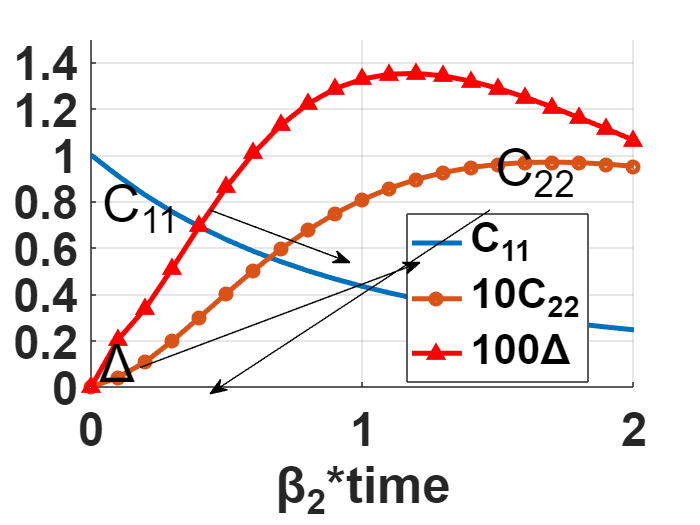

figure
hold on
fac=32;%factor for plotting
f=10;%factor
h(1)=plot(t,Cp(1,:),'-','linewidth',3);%C11
%h(2)=plot(t,-f*Cp(2,:),'--','linewidth',3);%C12--no need to plot
h(2)=plot(t,f*Cp(3,:),'-o','linewidth',3);%C22
%h(3)=plot(t,f*Cp(3,:),'-o','linewidth',3);%C33
h(3)=plot(t,10*f*delta,'-^r','linewidth',3);
%plot([0 max(t)],[0 0],'-r','linewidth',3)
set(gca,'YTick',0:.2:1.6)
set(gca, 'fontsize',28,'fontweight','bold');
xlabel('\beta_2*time')
legend('C_{11}','10C_{22}','100\Delta','Location','Best')
%text(1,.6,'C_{11}','fontsize',fac);
%gtext('\Delta','fontsize',fac); %allows clicking in plot to place text
%text(1.2,1.1,'\Delta','fontsize',fac) %text only
x = [0.2 0.6];%normalized units based on x and y span = 1
y = [0.3 0.5];
annotation('textarrow',x,y,'String','\Delta','fontsize',fac)

%text(0.5,.6,'C_{12}','fontsize',fac); %no need to plot
x = [0.3 0.5];
y = [0.6 0.5];
annotation('textarrow',x,y,'String','C_{11} ','fontsize',fac)

x = [0.7 0.3];
y = [0.6 0.25];
annotation('textarrow',x,y,'String','C_{22} ','fontsize',32)
grid on

## functions

function C = expdecay( beta,t )
%eta=beta(1)*exp(-beta(2)*t)
C=beta(1)*exp(-beta(2).*t);
end

function Xp=SSC_V4(beta,x,yfunc)
%Computes scaled sensitivity coefficients =Xp, nxp matrix
%Returns scaled sensitivity matrix in a cell array
%can have k dependent variables that are stacked in a column vector
%all y1s, then all y2s, ...last are yks
%n is the number of data
%p is the number of parameters
%Xp1 = dY/dbeta1~[y(beta1(1+d), beta2,...betap) - y(beta1,
%beta2,...betap)]/d...
%d is the arbitrary delta
%beta is the p x 1 parameter vector
%yhat is nx1 vector, the y values when only one parameter has been successively perturbed by d
%ypred is nx1 vector,  the y values when parameters are set to beta
%betain is px1 vector, the parameter values with only one parameter perturbed by d
%x are the independent variables (can be one or more independent variables)
%yfunc is a function (m file or an anonymous) defined by the user outside
%of this file

## X' = scaled sensitivity coefficients using forward-difference

This is a forward problem with known approximate parameters

d=0.001;
ypred=yfunc(beta,x);
for i = 1:length(beta)  %scaled sens coeff for forward problem
    betain = beta; %reset beta
    betain(i) = beta(i)*(1+d);
    yhat{i} = yfunc(betain,x);
    Xp{i} = (yhat{i}-ypred)/d;%scaled sens coeff for ith parameter
end
end